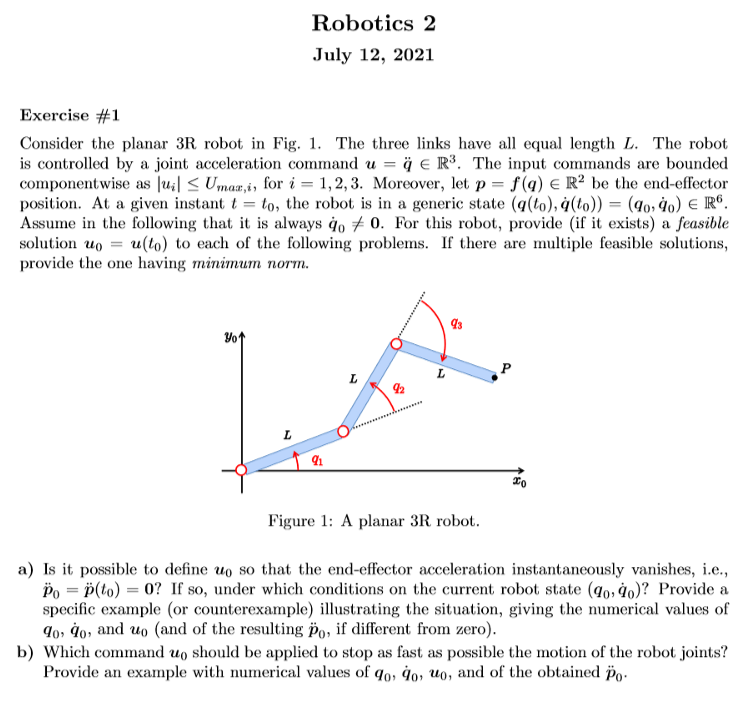

% % % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% 
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% % % 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% % % 

% % % 
% % % PC_EEShort.J
% % % PC_EEShort.f

% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z)

% PCVar.f_dot
% PC_EEShort.f
% PC_EEShort.J
% f
% J
% PC_EEShort.J_dot_short
% 

## defining Control output

% % lambda=sym('lambda','real')
% % a_sym=sym('a','real')
% % b_sym=sym('b','real')
% % u_sym=lambda*a_sym+b_sym
% % 
% % 

## U_max definition

% U_max=[15,10,10]'*pi
% q_=[0,pi/2,pi/2]'
% q_dot_=0.7*[pi,pi,0]'
% l_=[1,1,1]'
% to_replace=[z.q;z.q_dot;z.l]
% to_replace_=[q_;q_dot_;l_]

## Replacing values

% % J0_=subs(J,to_replace,to_replace_)
% % p0_=J0_*q_dot_
% % f0_fot_=subs(PCVar.f_dot,to_replace,to_replace_)
% % 
% % J0_dot_=subs(PC_EE.J_dot,to_replace,to_replace_)
% % J0_pinv_=pinv(J0_)
% % h0_=J0_dot_*q_dot_
% % 

## getting u

% % a_=-J0_pinv_*J0_*q_dot_
% % b_=-J0_pinv_*h0_
% % a_=vpa(a_)
% % b_=vpa(b_)
% % 
% % % with complete computations it follows manually
% 

## SNS algorithm case 1

% abs_on=true;
% autodetectsign=true
% J_=[-1,-1,0;0,1,1]
% h0_=[3;-4]*pi^2
% % [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)
% 
% [qdotstarFinal,W] = SNSMethod2(h0_,J_,U_max*0,-U_max,U_max)%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## SNS algorithm case 2

% abs_on=true;
% autodetectsign=true
% J_=sym([-1,-1,0;0,1,1])
% J_dot_=[7/4,11/4,11/4;-2,-2,0]*pi
% h0_=[105/16;-4]*pi^2
% [qdotstarFinal] = SNSMethod1(-h0_,J_,U_max,abs_on,autodetectsign)
% 
% % [qdotstarFinal,W] = SNSMethod2(h0_,J_,U_max*0,-U_max,U_max)%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## Exercise 2

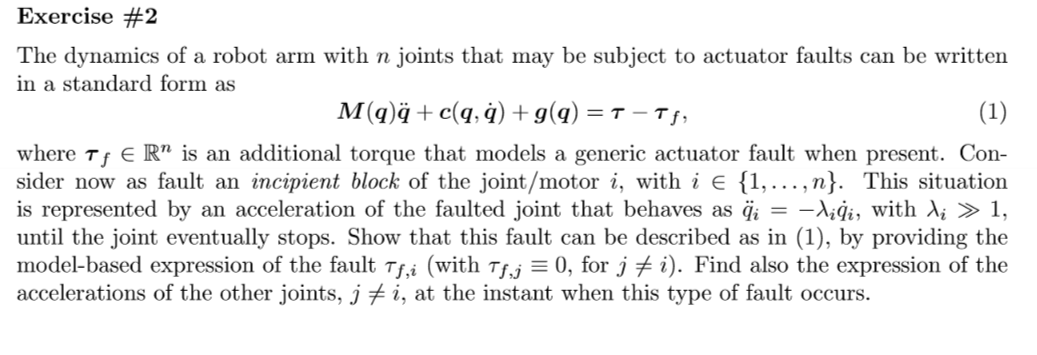

## Exercise 3

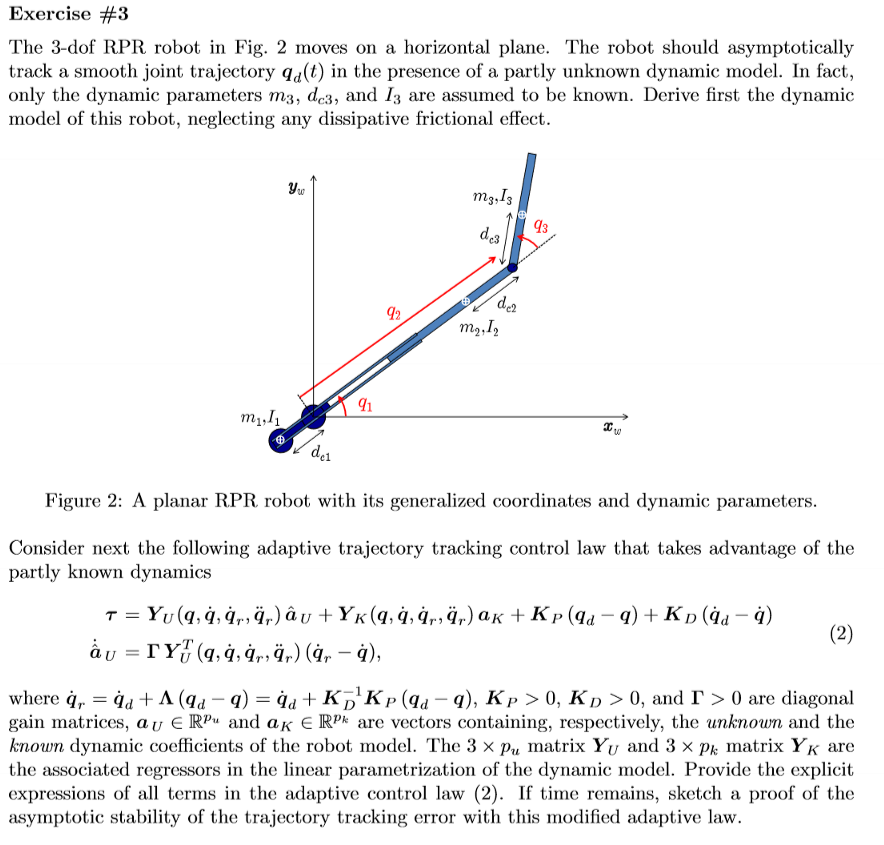

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,1,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rpr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% z.opt_expr={[l(1)],[0]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % %             0       , z.l(2)  , 0   , q(2);]

% % % 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Ti(1)
% Pc
% M
% % M(1,1)
% % M(1,2)
% % M(1,3)
% % M(2,2)
% % M(2,3)
% % M(3,3)

% [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[])
% % %[m1*dc1^2 + m2*dc2^2 + m3*dc3^2 + I1 + I2 + I3; m3*dc3^2 + I3; m2 + m3; dc3*m3; 2*dc2*m2]
% 

% % known_params=[z.m(3),z.dc(3),z.I(3)]'%z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
% known_params=[z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
% % [Msubs2, dynamicParameters2, aM2]=adaptative_control_get_paramateres2(M,dynamicParameters,aM,known_params,[])
% 
% [struct_sub_mat,params]=Adpatative_Control_parameters(Msubs,dynamicParameters,known_params,aM)
% % 

% % struct_sub_mat.new_submats_u
% % params.unknown_parameters
% % params.unknown_parameters_

% % isMotor=false
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% cac
% S

% % g_q
% % U{:}

% % % F_v=sym('F',[2,1],'real')
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)
% [All, dynamicParamsReturn, aM]= getDynamicParameters2([M,S],q,[z.q_dot],1)
% % [All, dynamicParamsReturn, aM]= getDynamicParameters([M,S],q,[],2)

% % All(:,4:end)
% % S_subs=simplify(expand(All(:,4:end)))

## Computing adaptative parameters

% known_params=[z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
% [struct_sub_mat,params]=Adpatative_Control_parameters(All,dynamicParamsReturn,known_params,aM)

% struct_sub_mat.new_submats_u
% struct_sub_mat.new_submats_k
% params.known_parameters
% params.known_parameters_
% params.unknown_parameters
% params.unknown_parameters_

% 

## linear paramatrization for unkown terms

% % % %complete model
% a_order_u = params.unknown_parameters([1,3,2])

% Msubs_u = struct_sub_mat.new_submats_u(:,1:3)
% Ssubs_u = struct_sub_mat.new_submats_u(:,4:6)
% % gSubs = diag(All(:,7:9))
% % FSubs = All(:,10:12)

% torqueSubs_u = Msubs_u*z.q_ddot + Ssubs_u*z.q_dot %+ gSubs +FSubs*qd

% [Y_u, Yshort_u]=getLinearParametrization(torqueSubs_u,a_order_u)

% Y_u

## linear paramatrization for kown terms

% % % %complete model
% a_order_k = params.known_parameters([1,2,3])
% params.known_parameters_([1,3,2])

% Msubs_k = struct_sub_mat.new_submats_k(:,1:3)
% Ssubs_k = struct_sub_mat.new_submats_k(:,4:6)
% % gSubs = diag(All(:,7:9))
% % FSubs = All(:,10:12)

% torqueSubs_k = Msubs_k*z.q_ddot + Ssubs_k*z.q_dot %+ gSubs +FSubs*qd

% [Y_k, Yshort_k]=getLinearParametrization(torqueSubs_k,a_order_k)

% Y_k

## Defining control law

% q_r=sym('q_r_',[n,1],'real')
% q_r_dot=sym('q_r_dot_',[n,1],'real')
% q_r_ddot=sym('q_r_ddot_',[n,1],'real')
% M_law=Msubs_u+Msubs_k
% S_law=Ssubs_u+Ssubs_k
% torqueSubs_r = Msubs_u*q_r_ddot+ Ssubs_u*q_r_ddot%+ gSubs +FSubs*qd

## Linearizing

% [Y_r, Yshort_r]=getLinearParametrization(torqueSubs_r,a_order_u)

% Y_r